# FMCW Radar Lab: Moving Target Indicator (MTI) Filtering

This script demonstrates how a moving target indicator (MTI) filter can be used to enable easier detection of moving targets. Radar data typically contains large reflections from static objects such as the ground, walls, trees, etc. termed "clutter". This clutter can make it difficult to see targets of interest, which are typically moving radially with respect to the radar.

In this lab, we filter out the static clutter to improve visibility of moving targets.

## System Setup

Before going through the lab, we prepare the workspace by clearing variables, closing figures, suppressing warnings.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

For this lab, we use many of the same parameters that were used in previous labs.

fc = 10e9;
prf = 250;
nPulses = 64;
fs = 1e6;
rampbandwidth = 500e6;
[rx,tx,bf,bf_TDD] = setupLabRadar(fc,prf,nPulses,fs,rampbandwidth);

## MTI Filter

In this workshop, we use a three-pulse canceler which is a popular and simple MTI filter. The canceler is an all-zero FIR filter with filter coefficients [1 -2 1]. This filter is applied across the pulses and effectively acts as a low pass filter to remove static reflections.

mti = [1 -1 0];
ncoeff = length(mti);

Use the following switch to toggle MTI filtering on and off.

applyFilter = false;

## Display

In this workshop, we look at two different ways to display the filtered data.

The range-Doppler plot is the same display that we looked at in the previous lab. This display shows the Range vs. Doppler response and is useful for visualizing moving target range. The Doppler-time plot shows the Doppler response over time. There is no range information, but it is useful for seeing how the Doppler profile changes over time.

displayType = "Range-Doppler";
minIntensity = 30;   %dB
maxIntensity = 100;  %dB

## Data Collection

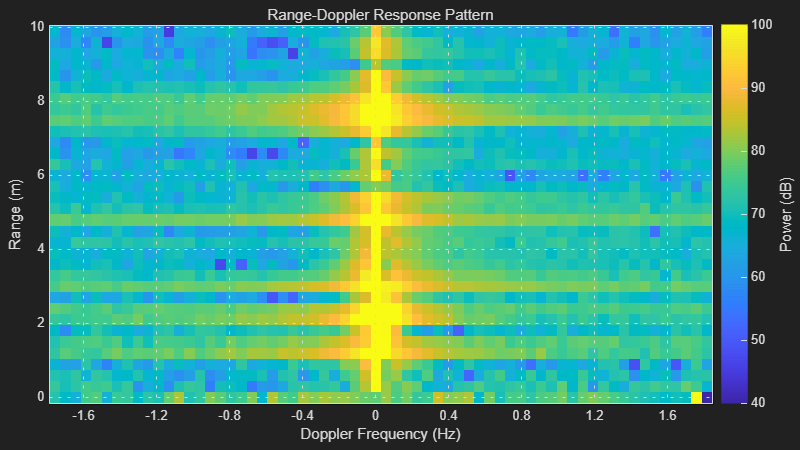

% Run time in seconds
tCapture = 30;

% Get the min and max ranges to include on the plot
minRange = 0;
maxRange = 10;

% Create a range-Doppler response for processing
tSweep = double(bf.FrequencyDeviationTime)/1e6;
sweepSlope = rampbandwidth/tSweep;
rd = phased.RangeDopplerResponse(DopplerOutput="Speed",...
    OperatingFrequency=fc,SampleRate=fs,RangeMethod="FFT",...
    SweepSlope=sweepSlope,PRFSource="Property",PRF=prf);

% Setup displays
if strcmp(displayType,"Range-Doppler")
    scope = phased.RangeDopplerScope(IQDataInput=false);
else
    % Adjustment factor to account for processing time, this is jsut to control time resolution on display
    tAdjust = 3;

    % Frequency difference between points in the Doppler domain. 
    df = prf/(nPulses-1); 

    % Setup the DTI scope to plot Doppler vs. Time
    scope = phased.DTIScope(IQDataInput=false,DopplerOutput='Speed',DopplerOffset=-prf/2,DopplerResolution=df,TimeSpan=tCapture,TimeResolution=1/prf*nPulses*tAdjust,OperatingFrequency=fc);
end
scope.Position = [50 50 800 450];
% Capture the first waveform which typically has 0 values
captureTransmitWaveform(rx,tx,bf);

t = tic;
while toc(t) < tCapture
    % capture data
    data = captureTransmitWaveform(rx,tx,bf);

    % Arrange data into pulses for processing
    data = arrangePulseData(data,rx,bf,bf_TDD);

    % Apply MTI filter, remove pulses in transient region
    if applyFilter
        data = filter(mti,1,data,[],2);
        data = data(:,ncoeff:end);
    end

    % Calculate the range-Doppler response
    [resp,range,speed] = rd(data);

    % Get range of interest
    keepRange = range >= minRange & range <= maxRange;

    % Set the min and max intensity levels of the plot
    keepRangeData = resp(keepRange,:);
    keepRangeDataMag = abs(keepRangeData);
    keepRangeDataPhase = angle(keepRangeData);
    clippedMag = clip(keepRangeDataMag, 10^(minIntensity/20), 10^(maxIntensity/20));
    keepRangeData = clippedMag .* exp(1j*keepRangeDataPhase);
    keepRangeData(1,1) = 10^(minIntensity/20);  %Set min intensity level
    keepRangeData(1,2) = 10^(maxIntensity/20);  %Set max intensity level

    % Plot the data
    if strcmp(displayType,"Range-Doppler")
        % Plot Range-Doppler
        scope(keepRangeData,range(keepRange),speed)
    else
        % Get Doppler response for this time step by averaging across ranges
        dopresp = mean(abs(keepRangeData),1)';
        scope(dopresp);
    end
end


% Disable TDD Trigger
cleanupAntenna(rx,tx,bf,bf_TDD);
